clear; close all

## A - Ensamble Kalman Filter

depth = 100;
depths = 1:depth;
load('travelTimeData');

See Ensamble Kalman filter function implementation at the bottom.

## 200 realisations

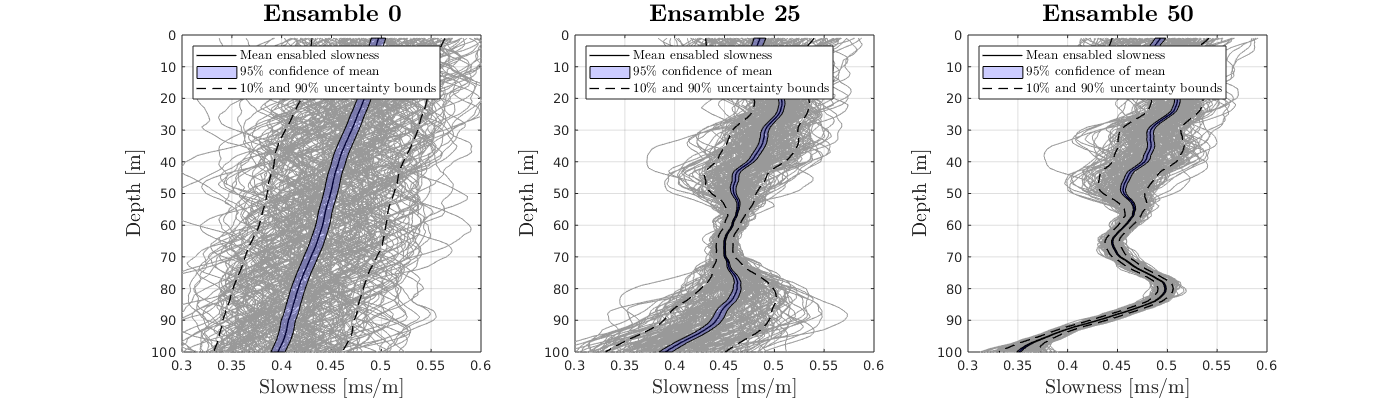

[slownessEnsamble_200, CovMat, L, MU] = genRealizations(200);
[slownessEnsamble_200_j_50, slownessEnsamble_200_j_25] = enKF(slownessEnsamble_200, travelTimeData, 1);
plot_ensample(slownessEnsamble_200_j_50, slownessEnsamble_200, slownessEnsamble_200_j_25);

## B - Change parameters

## 50 realisations

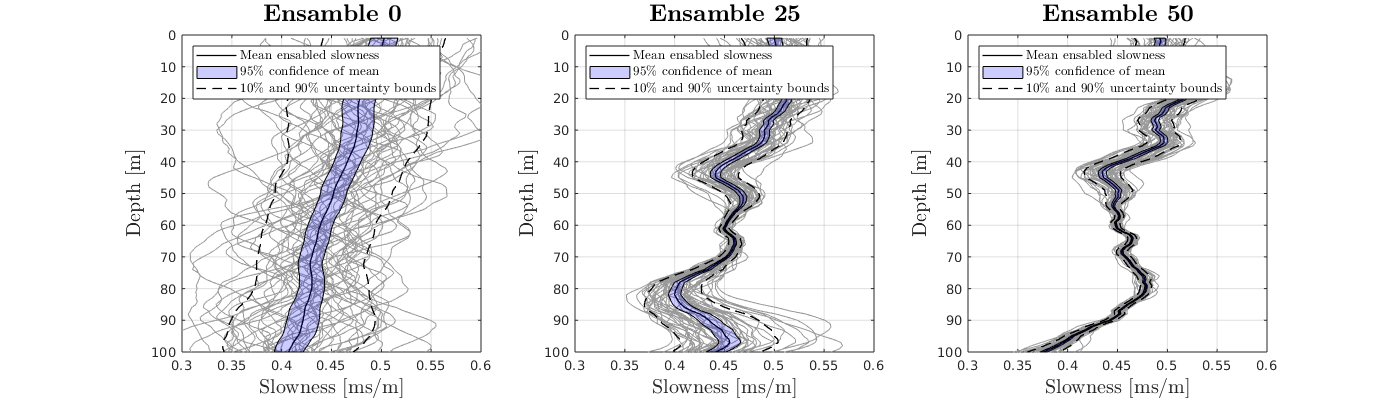

slownessEnsamble_50 = genRealizations(50);
[slownessEnsamble_50_j_50, slownessEnsamble_50_j_25] = enKF(slownessEnsamble_50, travelTimeData, 1);
plot_ensample(slownessEnsamble_50_j_50, slownessEnsamble_50, slownessEnsamble_50_j_25);

## 400 realisations

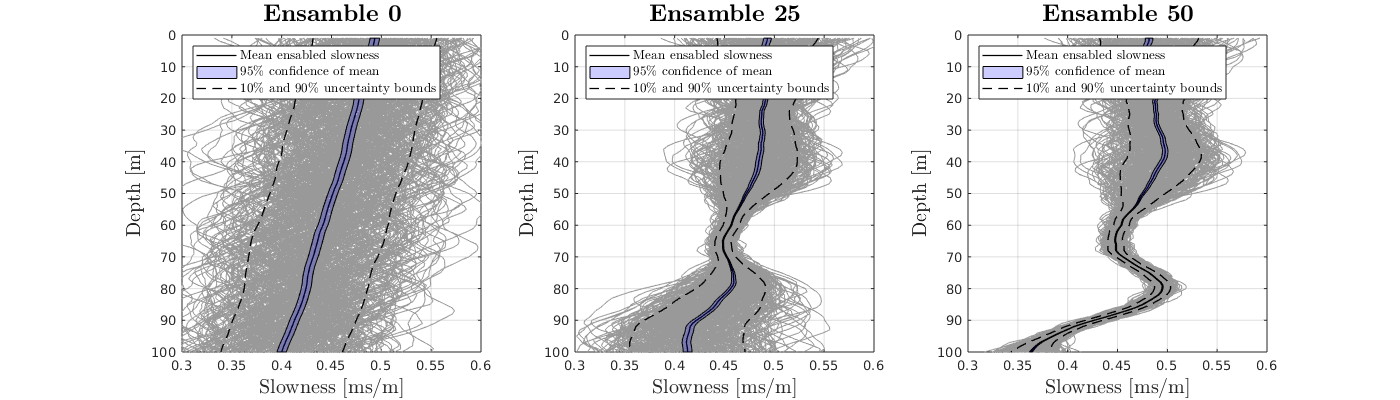

slownessEnsamble_400 = genRealizations(400);
[slownessEnsamble_400_j_50, slownessEnsamble_400_j_25] = enKF(slownessEnsamble_400, travelTimeData, 1);
plot_ensample(slownessEnsamble_400_j_50, slownessEnsamble_400, slownessEnsamble_400_j_25);

## Reversed 200 realisations

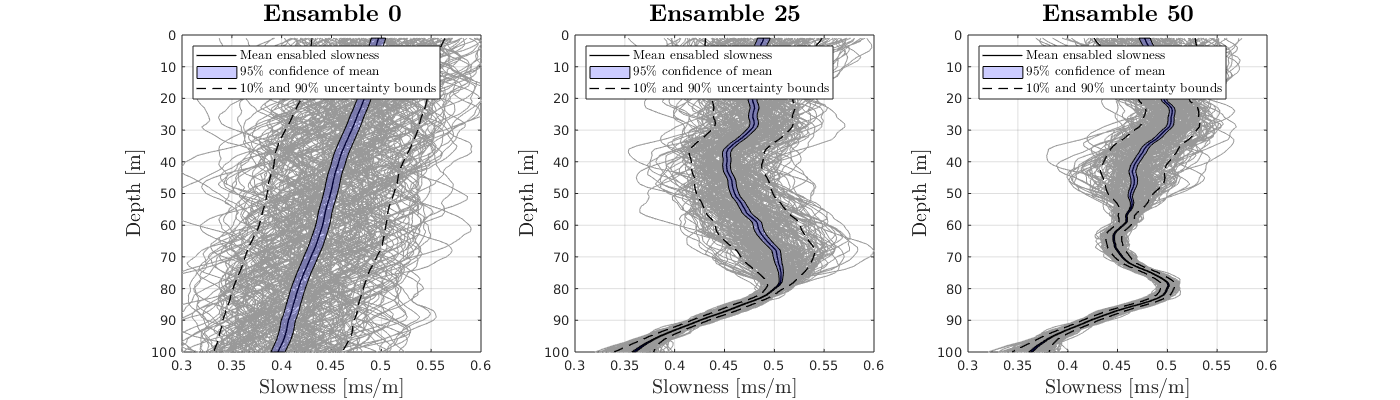

[slownessEnsamble_200_j_50_rev, slownessEnsamble_200_j_25_rev] = enKF(slownessEnsamble_200, travelTimeData, 0);
plot_ensample(slownessEnsamble_200_j_50_rev, slownessEnsamble_200, slownessEnsamble_200_j_25_rev);

## Reversed 50 realisations

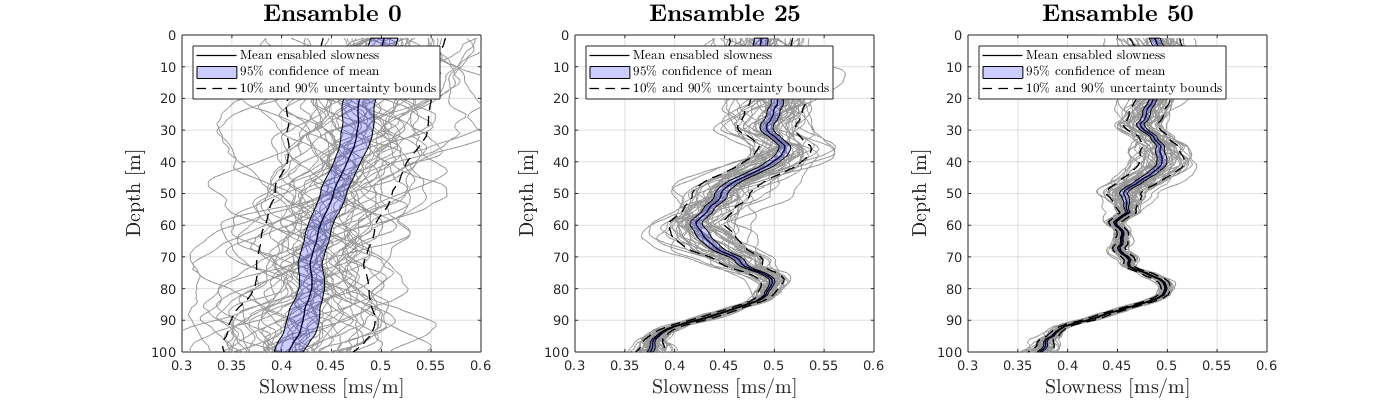

[slownessEnsamble_50_j_50_rev, slownessEnsamble_50_j_25_rev] = enKF(slownessEnsamble_50, travelTimeData, 0);
plot_ensample(slownessEnsamble_50_j_50_rev, slownessEnsamble_50, slownessEnsamble_50_j_25_rev);

## Reversed 400 realisations

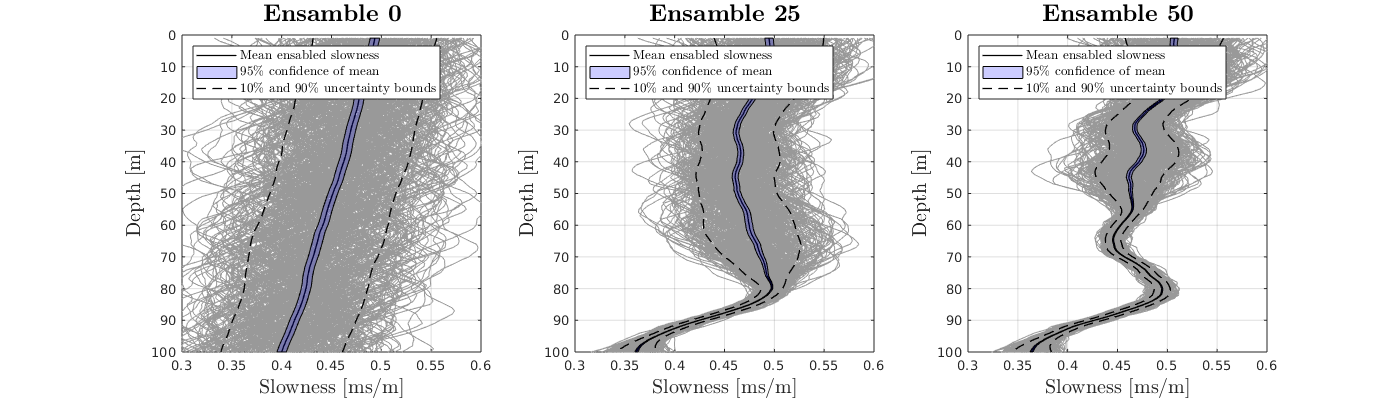

[slownessEnsamble_400_j_50_rev, slownessEnsamble_400_j_25_rev] = enKF(slownessEnsamble_400, travelTimeData, 0);
plot_ensample(slownessEnsamble_400_j_50_rev, slownessEnsamble_400, slownessEnsamble_400_j_25_rev);

#### Comments

The order in which the data is assimilated does not seem to matter as the mean and variance in both cases are very similar.

However, the amount of realizations used in the ensamble matters more. A lower amount results in a lower variance, and conversely, a larger amount increases the variance in the estimate.

## C - Kalman filter

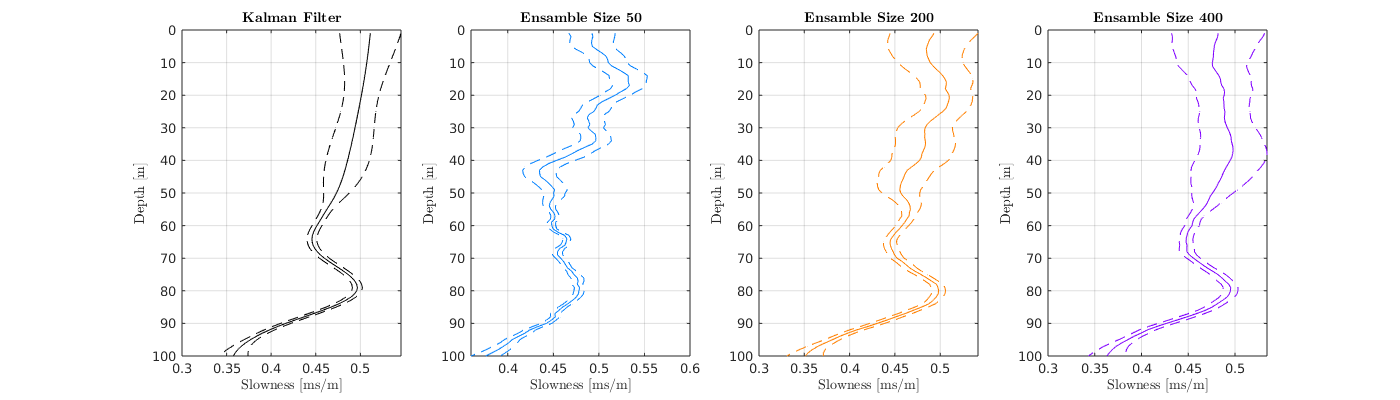

Sigma = CovMat;
mu = MU;
tau = 0.1;
g = zeros(1,100);
for j = 1:50
    angleToReceiver = atan2(40, 50 + j);
    g(1:50+j) = 1/cos(angleToReceiver);
    g(50+j:100) = 0;
    
    K = Sigma*g'/(g*Sigma*g' + tau^2);
    mu = mu + K*(travelTimeData(j) - g*mu);
    Sigma = Sigma - K*g*Sigma;
end

std_80_percent = (sqrt(diag(Sigma)))*norminv(0.8);
CI = [mu - std_80_percent, mu + std_80_percent];

% B = 200
slownessMean_200 = mean(slownessEnsamble_200_j_50, 2);
slownessVariance_200 = var(slownessEnsamble_200_j_50, 1, 2);
std_90_200 = sqrt(slownessVariance_200)*norminv(0.9);
CI_200 = [slownessMean_200 - std_90_200, slownessMean_200 + std_90_200];

% B = 50
slownessMean_50 = mean(slownessEnsamble_50_j_50, 2);
slownessVariance_50 = var(slownessEnsamble_50_j_50, 1, 2);
std_90_50 = sqrt(slownessVariance_50)*norminv(0.9);
CI_50 = [slownessMean_50 - std_90_50, slownessMean_50 + std_90_50];

% B = 400
slownessMean_400 = mean(slownessEnsamble_400_j_50, 2);
slownessVariance_400 = var(slownessEnsamble_400_j_50, 1, 2);
std_90_400 = sqrt(slownessVariance_400)*norminv(0.9);
CI_400 = [slownessMean_400 - std_90_400, slownessMean_400 + std_90_400];



plot_comparison(slownessMean_50, mu, CI_50, CI_200, CI_400, CI, slownessMean_200, slownessMean_400, depths);

Since the problem is linear and gaussian, the kalman filter will provide the exact solution. The higher number of realizations the closer the solution becomes. The mean converges towards the correct solutions as the number of realiseations increases. The unsertanty is underestimated at first, then becomes more corectly repreented as the number of realisations increase.

## Ensamble Kalmanfilter

function [slownessEnsamble_assimilate, slownessEnsamble_j_25] = enKF(slownessEnsamble, travelTimeData, order)
%ENKF function solves task (a)
%   given an ensamble and data, filters the ensamble using the data to
%   estimate parameters

s = size(slownessEnsamble);
depth = s(1);
B = s(2);

% preallocate
slownessTravelTimeCovariance = -ones(depth,1);
slownessEnsamble_assimilate = slownessEnsamble;

if order == 1
    sensors = 1:50;
else
    sensors = 50:-1:1;
end

for j = sensors % iterate through sensors
    
    % forecast travel time for sensor j; B times, one for each realization
    sensorTravelTimeEnsamble = forecastTravelTime(slownessEnsamble_assimilate, B, j);
    
    % calculate the travel time variance for sensor j
    travelTimesVariance = var(sensorTravelTimeEnsamble);
    
    % calculate covariance of travel with the slowness ensamble
    for k = 1:depth
         C = cov(slownessEnsamble_assimilate(k,:), sensorTravelTimeEnsamble); % 2x2 Covariance matrix
         slownessTravelTimeCovariance(k) = C(1,2);
    end
    
    % calc kalman gain and assimilate data into ensamble
    K = slownessTravelTimeCovariance / travelTimesVariance;
    for b = 1:B
        slownessEnsamble_assimilate(:,b) = slownessEnsamble_assimilate(:,b) + K*(travelTimeData(j) - sensorTravelTimeEnsamble(b));
    end
    
    if j == 25 % keeping track of the half-way/intermediate result
        slownessEnsamble_j_25 = slownessEnsamble_assimilate;
    end
    
end

end



## Forcast Traveltime


function travelTimes  = forecastTravelTime(ensamble, B, sensors)

m = length(sensors);
travelTimes = -ones(m, B);
tau = 0.1;

% iterate throung ensambles
for i = 1:B
    
    % iterate through the given receivers/sensors
    for j = 1:m
    
        % add up all slownesses down to depth of receiver j, of ensamble i
        sumSlowness = sum(ensamble(1:50 + sensors(j),i));
        
        angleToReceiver = atan2(40, 50 + sensors(j));
        noise = tau*randn(1);
        
        % travel time to receiver j, of ensamble i
        travelTimes(j, i) = sumSlowness/cos(angleToReceiver) + noise;
    end    
    
end

end


## Generate Realizations

function [ensamble, CovMat, L, mean_] = genRealizations(B)

layers = 100;

ensamble = -ones(layers, B);

CovMat = -ones(layers, layers);

sigma = 0.05;
mean_ = 0.5 - 0.001*(1:layers)';
eta = 0.1;

for i = 1:layers
    for j = 1:layers
        
        CovMat(i, j) = sigma^2 * (1 + eta*abs(i - j))*exp(-eta*abs(i - j));
        
    end
end

L = chol(CovMat)';

for i = 1:B
    ensamble(:, i) = mean_ + L*randn(layers, 1);
end


end